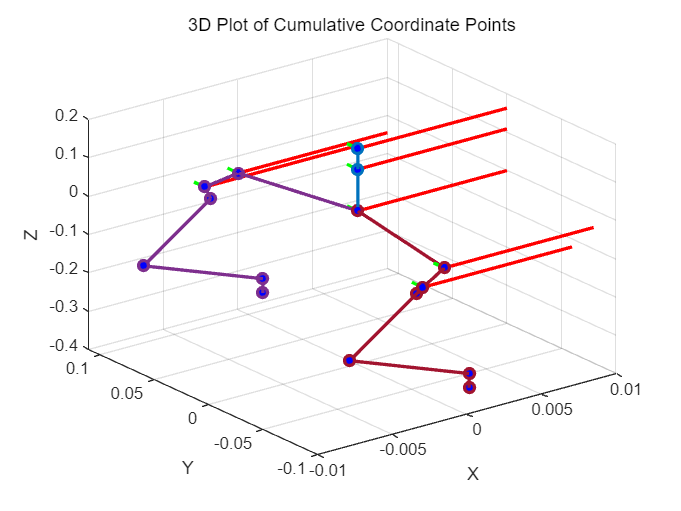

% 定义各个点的坐标
points = [

%% base link
     0 ,0, 0;                          % base_link
   -0.0043186, -0.027049, 0.10865;    % base_link_1
    0.00051856, 0, 0.0541;            % base_link_2
 
%% head
    0.004, 0.136, 0.027049;           % head_link_1
    0    ,0     ,  0.02865;           % head_link_2

%% left arm
     0.005, 0.096001, -0.083068;       % left_arm_1  
     0.002, 0.01215, 0;                % left_arm_2
     0.025, 0.1157, 0;                 % left_arm_3
     0, 0.00155, 0;                    % left_arm_4
     0.058959, 0.007175, 0.0021739;    % left_arm_5
     0.1257, 0, 0;                     % left_arm_6

%% right arm
    0.0044814, 0.095801, 0.13717;     % right_arm_1
    0.002, -0.00515, 0;               % right_arm_2
    0.025001, -0.1007, 0;             % right_arm_3
    0, -0.0018, 0;                    % right_arm_4
    -0.003175, -0.058999, 0;          % right_arm_5
    0.12561, 0.0046316, 0;            % right_arm_6

%%  foot

     -0.00110,  0.095,   -0.013327;   % left_hip_pitch
     -0.00185,  0.0055,   -0.024;    % left_hip_roll
     0,        -0.0055,  -0.02315;   % left_hip_yaw
    -0.0045,   0.0000,  -0.128;      % left_knee_jo
     0.008,     0,        -0.118;    % left_foot_y_jo
     0,         0  ,  -0.037;        % left_foot_x_jo


    -0.00110, -0.095,   -0.013327;   % right_hip_pitch 
    -0.00185,  -0.0055,   -0.024;    % right_hip_roll
     0         ,0.0055,  -0.02315;   % right_hip_yaw
    -0.0045,   0.0000,  -0.128;      % right_knee_jo
     0.008,     0,        -0.118;    % right_foot_y_jo
     0,         0,    -0.037;        % right_foot_x_jo
];

% 定义六个相对坐标点
relative_coords1 = [

 %% base link
     0 ,0, 0;                          % base_link
   -0, 0, 0.10865;    % base_link_1
    0, 0, 0.0541;            % base_link_2

];
absolute_coords1 = zeros(size(relative_coords1));
absolute_coords1(1, :) = relative_coords1(1, :);
for i = 2:size(relative_coords1, 1)
    absolute_coords1(i, :) = absolute_coords1(i-1, :) + relative_coords1(i, :);
end

x1 = absolute_coords1(:,1);
y1 = absolute_coords1(:,2);
z1 = absolute_coords1(:,3);

% 绘制3D散点图并连接线段
figure (1);
plot3(x1, y1, z1, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);
title('3D Plot of Cumulative Coordinate Points');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;
hold on;

%为每个点绘制局部坐标系
scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x1(i), x1(i) + scale], [y1(i), y1(i)], [z1(i), z1(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x1(i), x1(i)], [y1(i), y1(i) + scale], [z1(i), z1(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x1(i), x1(i)], [y1(i), y1(i)], [z1(i), z1(i) + scale], 'b', 'LineWidth', 2);
end


% 定义六个相对坐标点
relative_coords2 = [
  0 ,0,0;
    -0.00110,  0.095,   -0.013327;   % left_hip_pitch
     -0.00185,  0.0055,   -0.024;    % left_hip_roll
     0,        -0.0055,  -0.02315;   % left_hip_yaw
    -0.0045,   0.0000,  -0.128;      % left_knee_jo
     0.008,     0,        -0.118;    % left_foot_y_jo
     0,         0  ,  -0.037;        % left_foot_x_jo
];
absolute_coords2 = zeros(size(relative_coords2));
absolute_coords2(1, :) = relative_coords2(1, :);
for i = 2:size(relative_coords2, 1)
    absolute_coords2(i, :) = absolute_coords2(i-1, :) + relative_coords2(i, :);
end

x2 = absolute_coords2(:,1);
y2 = absolute_coords2(:,2);
z2 = absolute_coords2(:,3);

% 绘制3D散点图并连接线段
hold on
plot3(x2, y2, z2, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);
title('3D Plot of Cumulative Coordinate Points');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on
hold on

%为每个点绘制局部坐标系
scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x2(i), x2(i) + scale], [y2(i), y2(i)], [z2(i), z2(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x2(i), x2(i)], [y2(i), y2(i) + scale], [z2(i), z2(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x2(i), x2(i)], [y2(i), y2(i)], [z2(i), z2(i) + scale], 'b', 'LineWidth', 2);
end
hold on

% 定义六个相对坐标点
relative_coords3 = [

      0      ,0      , 0;         
    -0.00110, -0.095,   -0.013327; % right_hip_pitch 
    -0.00185,  -0.0055,   -0.024;    % right_hip_roll
     0         ,0.0055,  -0.02315;  % right_hip_yaw
    -0.0045,   0.0000,  -0.128;    % right_knee_jo
     0.008,     0,        -0.118;    % right_foot_y_jo
     0,         0,    -0.037;    % right_foot_x_jo
];
absolute_coords3 = zeros(size(relative_coords3));
absolute_coords3(1, :) = relative_coords3(1, :);
for i = 2:size(relative_coords3, 1)
    absolute_coords3(i, :) = absolute_coords3(i-1, :) + relative_coords3(i, :);
end

x3 = absolute_coords3(:,1);
y3 = absolute_coords3(:,2);
z3 = absolute_coords3(:,3);

% 绘制3D散点图并连接线段
hold on
plot3(x3, y3, z3, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);
title('3D Plot of Cumulative Coordinate Points');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on
hold on

%为每个点绘制局部坐标系
scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x3(i), x3(i) + scale], [y3(i), y3(i)], [z3(i), z3(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x3(i), x3(i)], [y3(i), y3(i) + scale], [z3(i), z3(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x3(i), x3(i)], [y3(i), y3(i)], [z3(i), z3(i) + scale], 'b', 'LineWidth', 2);
end

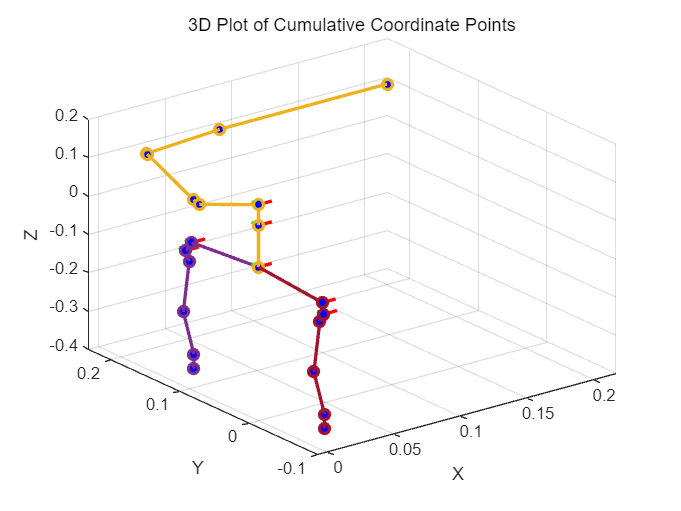

% 定义六个相对坐标点
relative_coords4 = [
     0 ,0, 0;                          % base_link
   -0, 0, 0.10865;                     % base_link_1
    0, 0, 0.0541;                      % base_link_2
    0.005, 0.096001, -0.083068;        % left_arm_1  
     0.002, 0.01215, 0;                % left_arm_2
     0.025, 0.1157, 0;                 % left_arm_3
     0, 0.00155, 0;                    % left_arm_4
     0.058959, 0.007175, 0.0021739;    % left_arm_5
     0.1257, 0, 0;                     % left_arm_6
   
];
absolute_coords4 = zeros(size(relative_coords4));
absolute_coords4(1, :) = relative_coords4(1, :);
for i = 2:size(relative_coords4, 1)
    absolute_coords4(i, :) = absolute_coords4(i-1, :) + relative_coords4(i, :);
end

x4 = absolute_coords4(:,1);
y4 = absolute_coords4(:,2);
z4 = absolute_coords4(:,3);

% 绘制3D散点图并连接线段
hold on
plot3(x4, y4, z4, '-o', 'MarkerFaceColor', 'blue', 'LineWidth', 2);
title('3D Plot of Cumulative Coordinate Points');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on
hold on

%为每个点绘制局部坐标系
scale = 0.01; % 坐标系轴的长度
for i = 1:length(x)
    % 绘制X轴
    plot3([x4(i), x4(i) + scale], [y4(i), y4(i)], [z4(i), z4(i)], 'r', 'LineWidth', 2);
    % 绘制Y轴
    plot3([x4(i), x4(i)], [y4(i), y4(i) + scale], [z4(i), z4(i)], 'g', 'LineWidth', 2);
    % 绘制Z轴
    plot3([x4(i), x4(i)], [y4(i), y4(i)], [z4(i), z4(i) + scale], 'b', 'LineWidth', 2);
end